# Discrete-Time Systems, Frequency Response

Name: Zhanna Klimanova

Student Id.: 260601438

## Exercise 1

- *Stable/Unstable: every bounded input produces a bounded output for all time in a stable system (BIBO), meaning that from*$-\infty$*to *$+\infty$*the amplitude of the signal has to be finite.*

- *Causal/Anti-Causal: the output depends only on the current and past inputs, not on future inputs. An anti-causal system is one where the output depends only on future inputs.*

- *Linear/Non-Linear: obeys the superposition and scalabiliy or in other words called the Law of Additivity and Law of Homogeneity. *

- *Time-Variant/Time-Invariant: the system's response to inputs do not change with time (a shift in the input produces a shift in the output).*

- *Memoryless/Not-Memoryless: the output at a given time is dependent only on the input at that same time.*

### **System 1: **


$$y[n] = e^{nx[n]}}$$


- ***Unstable: ****increasing/decreasing the *$n$* value causes the output amplitude to increase until *$\pm\infty$*. *

- ***Causal: ****the output at any time *$n$* depends on current and past values of *$x[n]$*.*

- ***Non-Linear: ****the system does not obey the superposition property. For example, setting *$x[n] = x_1[n] + x_2[n]$ and plugging into $y[n]$, it is expected to get $y_1[n] + y_2[n]$. The derivation shows that $e^{n(x_1[n] + x_2[n])} = e^{nx_1[n] + nx_2[n]} = e^{nx_1[n] } * e^{nx_2[n]} \neq y_1[n] + y_2[n]$.

- ***Time Variant:**** shift the *$y[n]$* by *$n_0$* such that *$y[n-n_0] = e^{(n-n_0)x[n-n_0]}$. *Shift the input of to *$x$* such that *$x[n-n_0]$* and plug back into equation *$e^{nx[n-n_0]}$*. The two shifts are not equivalent and the system is therefore time variant.*

- ***Memoryless: ****the output at any time *$n$* depends only on the input at that same time *$n$*. For example, at *$n=0$*, *$y[1]=e^{1x[1]}$* the output depends on the present value of *$x[n]$*.*

### **System 2: **


$$y[n] = x[n] - u[n+1]$$


- ***Stable: ****since *$u[n+1]$* is bounded, if the input *$x[n]$* is bounded, the output will also be bounded.*

- ***Anti-Causal: ****output at time *$n$* depends on the future value at *$n+1$*.*

- ***Non-Linear: ****the system does not obey the superposition property. For example, setting *$x[n] = x_1[n] + x_2[n]$* and plugging into *$y[n]$*, it is expected to get *$y_1[n] + y_2[n] = (x_1[n] - u[n+1]) + (x_2[n] - u[n+1]) = x_1[n] + x_2[n] - 2u[n+1]$. *The derivation shows that *$(x_1[n] + x_2[n]) - u[n+1] = x_1[n] + x_2[n] - u[n+1] \neq y_1[n] + y_2[n]$*.*

- ***Time Variant:**** shift the *$y[n]$* by *$n_0$* such that *$y[n-n_0] = x[n-n_0] - u[(n-n_0) +1]$. *Shift the input of to *$x$* such that *$x[n-n_0]$* and plug back into equation *$x[n-n_0] - u[n+1]$*. The two shifts are not equivalent and the system is therefore time variant.*

- ***Memoryless: ****the output at any time *$n$ depends only on a present value since for $u[n+1]$ it is known that $u[n]$ will be 1 when $n \ge 0$and will be 0 for $n < 0$. Therefore, $u[n-1]$ will be 1 when $n \ge -1$such that $y[n] = x[n] - 1$ and $u[n-1]$ will be 0 when $n < -1$ such that $y[n] = x[n] - 0$. 

### **System 3: **


$$y[n] = ax[n] + b$$


- ***Stable:**** if *$a$*, *$b$* are finite and *$x[n]$* is bounded.*

- ***Causal: ****the output at any time *$n$* depends on current and past values of *$x[n]$*.*

- ***Non-Linear: ****the system does not obey the superposition property. For example, setting *$x[n] = x_1[n] + x_2[n]$* and plugging into *$y[n]$*, it is expected to get *$y_1[n] + y_2[n] = (ax_1[n] + b) + (ax_2[n] + b)$*. The derivation shows that *$a(x_1[n] + x_2[n]) + b = ax_1[n] + ax_2[n] + b \neq y_1[n] + y_2[n] $*. HOWEVER, the system can be ****Linear ****if the constant b = 0.*

- ***Time Invariant: ****the system is performing time shifting so it will most likely be time invariant as a result. Firstly, shift the *$y[n]$* by *$n_0$* such that *$y[n-n_0] = ax[n-n_0]+b$*. Secondly, shift the inputs to *$x$* such that *$x[n-n_0]$* and plug back into equation *$x[n-n_0]+b$*. The two are equivalent and the system is therefore time invariant.*

- ***Memoryless: ****the output at any time *$n$* depends only on the input at that same time *$n$*. For example, at *$n=0$*, *$y[0]=ax[0] + b$* the output depends on the present value of *$x[n]$*.*

**Sources used to complete this section:**

- [https://www.youtube.com/watch?v=ngJ2QWvMPbI&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=ngJ2QWvMPbI&ab_channel=NesoAcademy)

- [https://www.youtube.com/watch?v=IdwpoS7YeJA&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=IdwpoS7YeJA&ab_channel=NesoAcademy)

- tutorialspoint.com/signals-and-systems-stable-and-unstable-system

- https://math.stackexchange.com/questions/3270918/the-system-yn-c-cdot-xn-d-is-given-is-the-system-linear-time-invarian

- [https://www.tutorialspoint.com/signals-and-systems-causal-non-causal-and-anti-causal-signals](https://www.tutorialspoint.com/signals-and-systems-causal-non-causal-and-anti-causal-signals)

- [https://www.youtube.com/watch?v=mqwUtn5cip8&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=mqwUtn5cip8&ab_channel=NesoAcademy)

- [https://www.youtube.com/watch?v=wOQDGvCLOs8&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=wOQDGvCLOs8&ab_channel=NesoAcademy)

- [https://www.youtube.com/watch?v=LezLNMznZm4&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=LezLNMznZm4&ab_channel=NesoAcademy)

- [https://www.youtube.com/watch?v=0sRAMfPUQ58&ab_channel=NesoAcademy](https://www.youtube.com/watch?v=0sRAMfPUQ58&ab_channel=NesoAcademy)

## Exercise 2

### Part 1

**Proving that the block diagram in Figure 1.a is equivalent to the one in Figure 1.b. In other words, proving the commutativity of the convolution sum.**

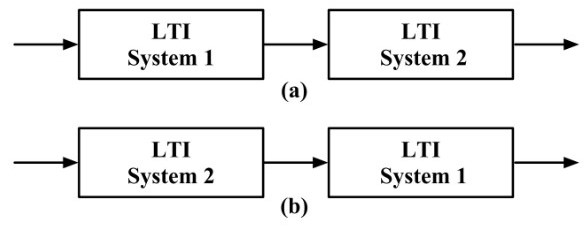

*System 1 = *$s_1[n]$

*System 2 = *$s_2[n]$


$$(s_1 * s_2)[n] = s_1[n]*s_2[n] = \sum^\infty_{k=-\infty}s_1[k] s_2[n-k]$$


*Using the following equivalences:*


$$K=n-k \text{ such that } k = n - K  \\
k={\infty} \text{ then } K=-{\infty} \\
k=-{\infty} \text{ then } K={\infty}$$


*The original convolution sum can be rewritten by substituting *$k = n-K$*:*


$$y[n] = \sum^\infty_{K=-\infty}s_1[n-K]s_2[n-(n-K)] =  \sum^\infty_{K=-\infty}s_2[K]s_1[n-K]$$


*Observing that the range of *$k$* and *$K$*are the same, the following equivalence can be derived giving that *$s_1*s_2=s_2*s_1$*:*


$$y[n] = \sum^\infty_{K=-\infty}s_2[K]s_1[n-K]= \sum^\infty_{k=-\infty}s_2[k]s_1[n-k]=s_2[n]*s_1[n]$$


### **Part 2**

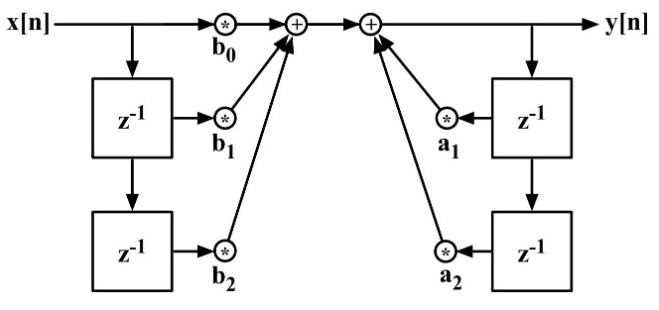


$$\begin{array}{rl}
y[n]= & b_0x[n]+b_1x[n-1]+b_2x[n-2]+a_1y[n-1]+a_2y[n-2]\\
= & \left(x[n]\right)b_0 +\left(x[n]*z^{-1}\right)b_1+\left(x[n]*z^{-1}*z^{-1}\right)b_2+\left(y[n]*z^{-1}\right)a_1+\left(y[n]*z^{-1}*z^{-1}\right)a_2\\
= &  \left(x[n]\right)b_0 +\left(z^{-1}*x[n]\right)b_1+\left(z^{-1}*z^{-1}*x[n]\right)b_2+\left(z^{-1}*y[n]\right)a_1+\left(z^{-1}*z^{-1}*y[n]\right)a_2\\
= & \left(x[n]\right)b_0+\left(z^{-1}*b_1x[n]\right)+\left(z^{-1}*z^{-1}*b_2x[n]\right)+\left(z^{-1}*a_1y[n]\right)+\left(z^{-1}*z^{-1}*a_2y[n]\right)\\
= & \left(x[n]\right)b_0+\left(z^{-1}*\left(b_1x[n]+ a_1y[n]+\left(z^{-1}*b_2x[n]\right)+\left(z^{-1}*a_2y[n]\right)\right)\\
= & \left(x[n]\right)b_0+\left(z^{-1}*\left(b_1x[n]+ a_1y[n]+z^{-1}*\left(b_2x[n]+a_2y[n]\right)\right) \\
= & b_0x[n]+ b_1x[n-1]+ a_1y[n-1]+b_2x[n-2]+a_2y[n-2]\\
= & b_0x[n]+b_1x[n-1]+b_2x[n-2]+a_1y[n-1]+a_2y[n-2]
\end{array}$$


*Applying the commutativity of the convolution sum, the simplified flow diagram that uses only two 1-sample delays is displayed below.*

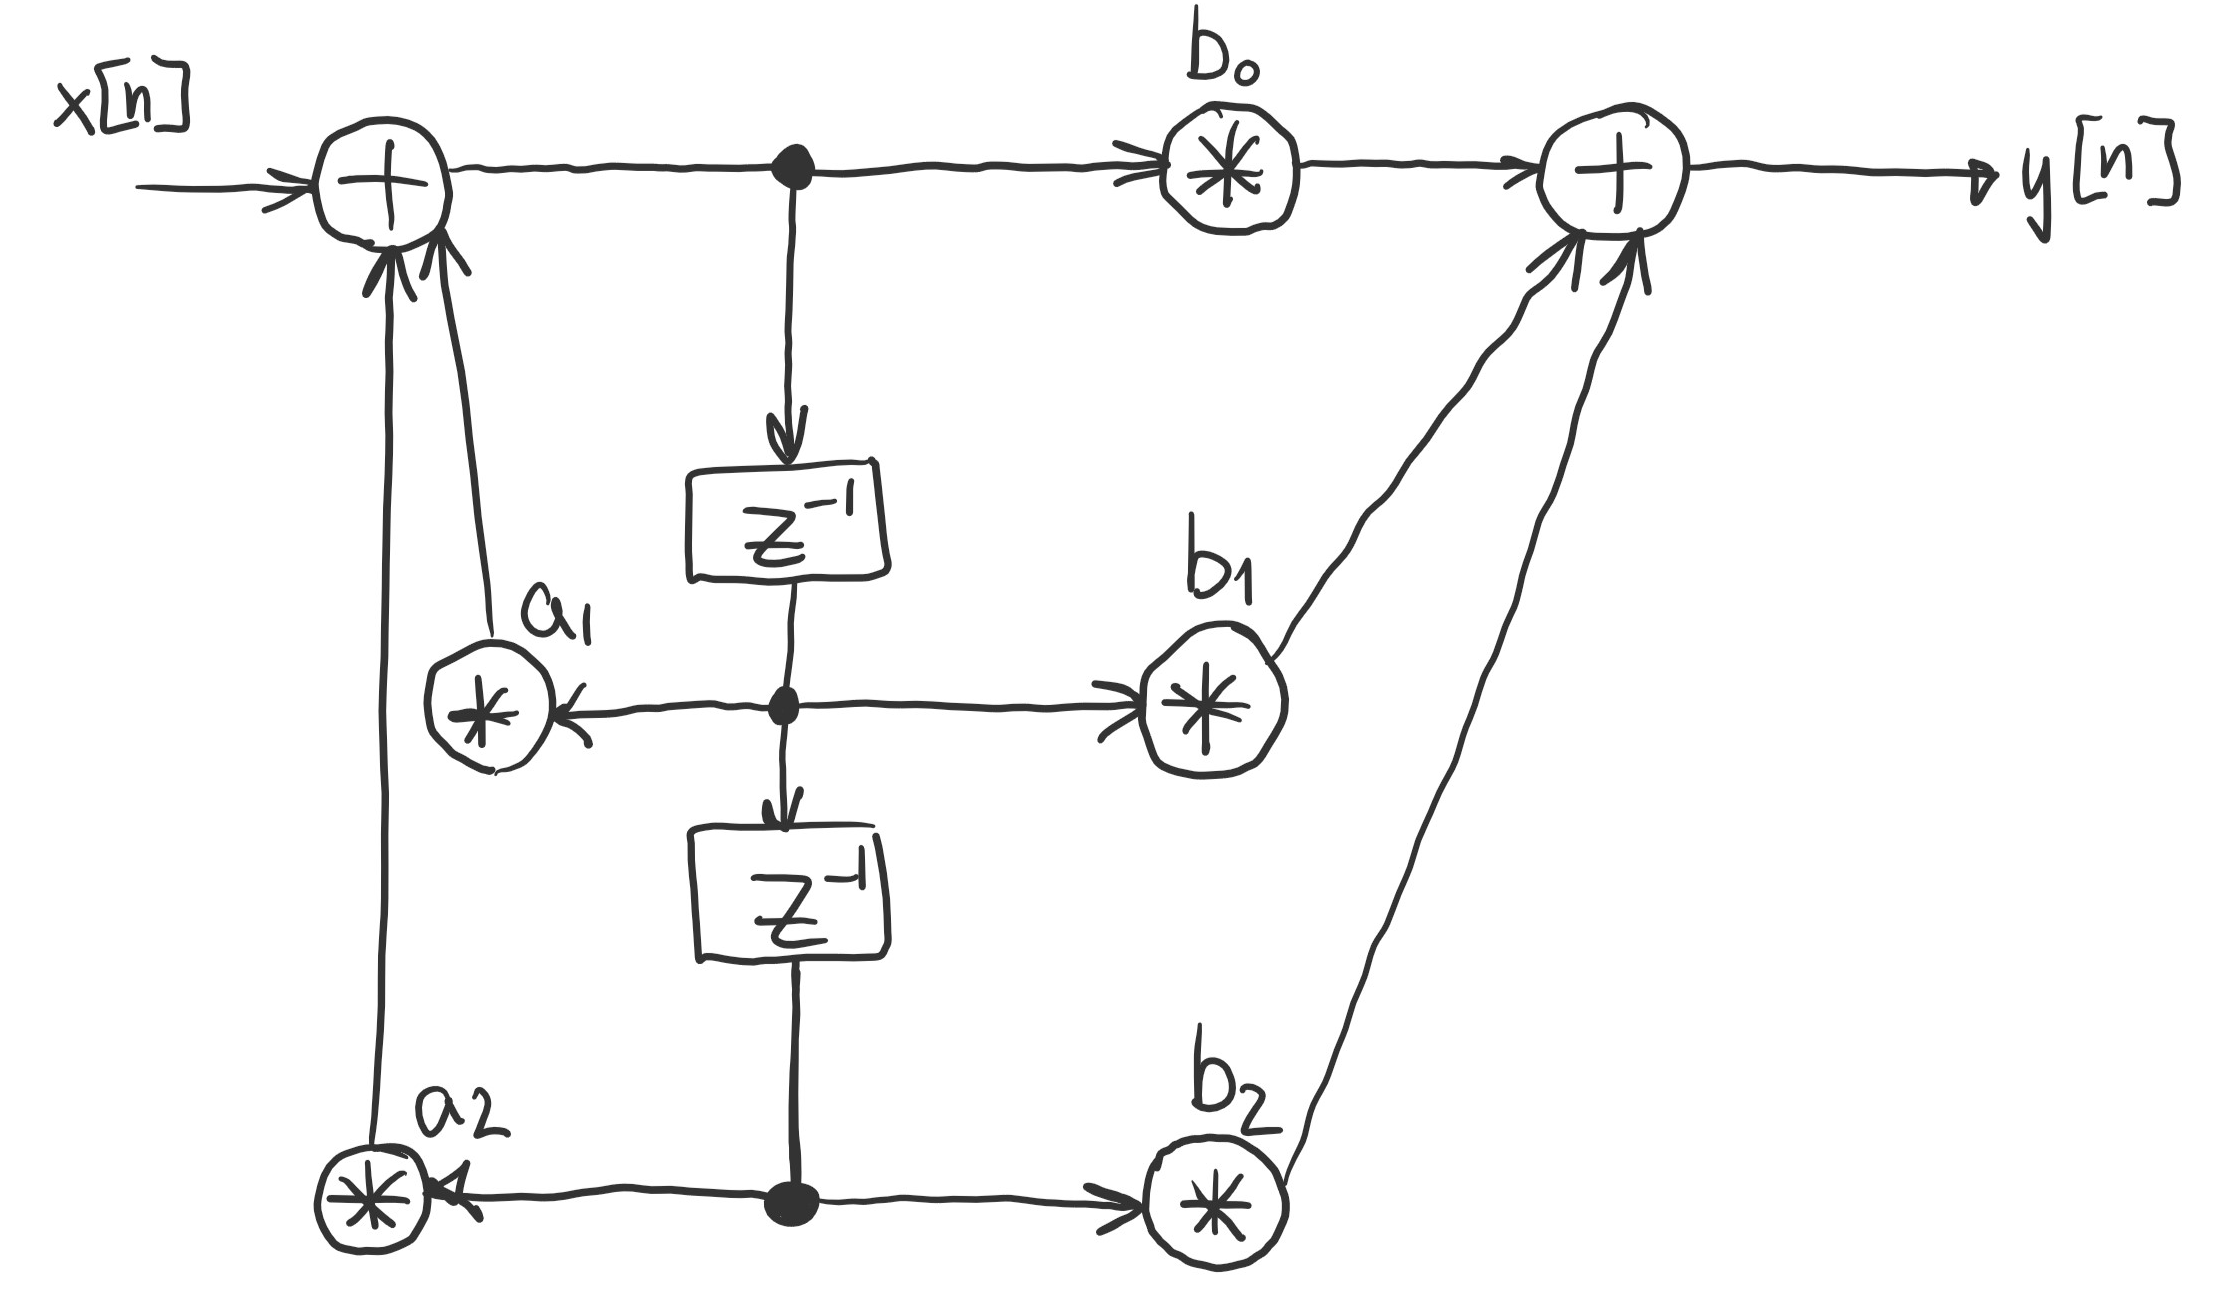

### Part 3

*The frequency response *$H(\omega) = \frac{Y(\omega)}{X(\omega)}$* of the system *$y[n] = b_0 x[n] + b_1 x[n-1] + b_2 x[n-2] - a_1 y[n-1] - a_2 y[n-2]$* is derived below:*


$$y[n] = b_0 x[n] + b_1 x[n-1] + b_2 x[n-2] - a_1 y[n-1] - a_2 y[n-2] \\
Y(\omega) - a_1e^{-j\omega}Y(\omega) - a_2 e^{-j2\omega} Y(\omega) = b_0X[\omega] + b_1e^{-j\omega}X[\omega]  + b_2e^{-j2\omega}X{\omega} \\
Y(\omega)(1-a_1e^{-j\omega}-a_2 e^{-j2\omega}) = X{\omega}(b_0+b_1e^{-j\omega}+b_2e^{-j2\omega}) \\
H[\omega] = \frac{Y(\omega)}{X{\omega}} = \frac{(b_0+b_1e^{-j\omega}+b_2e^{-j2\omega})}{(1-a_1e^{-j\omega}-a_2 e^{-j2\omega})} 
$$


**Sources used to complete this section:**

- [https://www.dsprelated.com/freebooks/filters/Direct_Form_II.html](https://www.dsprelated.com/freebooks/filters/Direct_Form_II.html)

- [https://www.youtube.com/watch?v=ap1qXBTKU8g&list=PLbqhA-NKGP6Afr_KbPUuy_yIBpPR4jzWo&index=8&ab_channel=AkashMurthy](https://www.youtube.com/watch?v=ap1qXBTKU8g&list=PLbqhA-NKGP6Afr_KbPUuy_yIBpPR4jzWo&index=8&ab_channel=AkashMurthy)

- [https://www.youtube.com/watch?v=mRKPGt97ytw&ab_channel=Engg-Course-Made-Easy](https://www.youtube.com/watch?v=mRKPGt97ytw&ab_channel=Engg-Course-Made-Easy)

- [https://eng.libretexts.org/Bookshelves/Electrical_Engineering/Signal_Processing_and_Modeling/Signals_and_Systems_(Baraniuk_et_al.)/04%3A_Time_Domain_Analysis_of_Discrete_Time_Systems/4.04%3A_Properties_of_Discrete_Time_Convolution](https://eng.libretexts.org/Bookshelves/Electrical_Engineering/Signal_Processing_and_Modeling/Signals_and_Systems_(Baraniuk_et_al.)/04%3A_Time_Domain_Analysis_of_Discrete_Time_Systems/4.04%3A_Properties_of_Discrete_Time_Convolution)

- [https://httpsachinbagul.files.wordpress.com/2017/12/lec-10.pdf](https://httpsachinbagul.files.wordpress.com/2017/12/lec-10.pdf)

- [https://www.youtube.com/watch?v=yuS86,oimY5Y&ab_channel=ECAcademy](https://www.youtube.com/watch?v=yuS86oimY5Y&ab_channel=ECAcademy)

- https://www.youtube.com/watch?v=Jl6dapilt58&ab_channel=JohnBuck

## Exercise 3

### **Part 1: Computing the Frequency Response**

**The difference equations **$y[n] = v[n-M] - gv[n]$** and **$v[n] = x[n]  + gv[n-M]$** can be used to describe the system in the figure below. Using the two equations, the frequency response **$H(\omega) = \frac{Y(\omega)}{X(\omega)}$ **can be computed.**

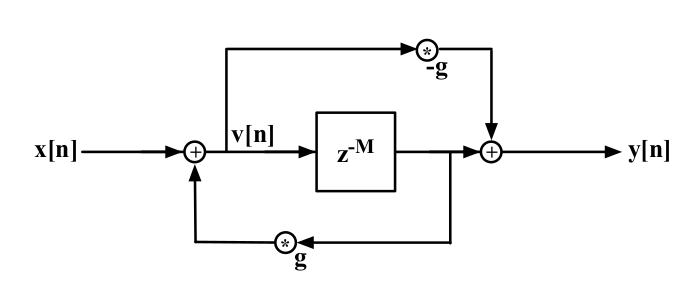

*The transfer function *$H(\omega) = \frac{Y(\omega)}{X(\omega)}$*, describes the steady-state response of a system to sinusoidal inputs of varying frequencies. In other words it is how a sinusoidal signal of a given frequency is affected by the filter. *

*Rearranging *$v[n] = x[n]  + gv[n-M]$* to get *$v[n] - gv[n-M] = x[n]$*.Taking the DTFT on both sides of the equation:*


$$V(\omega) - ge^{-jM\omega}V(\omega) = X(\omega) \\
V(\omega)(1 - ge^{-jM\omega}) = X(\omega) \\
V(\omega) = \frac{X(\omega)}{(1 - ge^{-jM\omega})} $$


*Taking the DTFT on both sides of the equation *$y[n] = v[n-M] - gv[n]$*:*


$$Y(\omega) = e^{-jM\omega}V(\omega) - gV(\omega) \\
Y(\omega) = V(\omega)(e^{-jM\omega} - g) \\$$


*Substituting *$V(\omega)$*into *$Y(\omega)$* to obtain*$H(\omega)$*:*


$$Y(\omega) =\frac{X(\omega)}{(1 - ge^{-jM\omega})} (e^{-jM\omega} - g) \\
Y(\omega) =X(\omega)\frac{(e^{-jM\omega} - g) }{(1 - ge^{-jM\omega})} \\
H(\omega) = \frac{Y(\omega)}{X(\omega)} = \frac{(e^{-jM\omega} - g) }{(1 - ge^{-jM\omega})}$$


### **Part 2: Plotting the Frequency and Phase Responses **

*The frequency response appears to have positive magnitude for all omega inputs which suggests this may be an all-pass filter.*

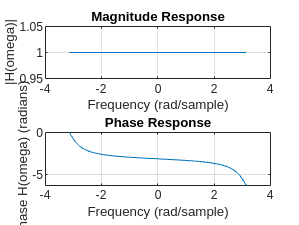

% Given values
g = 0.7;
M = 1000;
omega = linspace(-pi, pi, M); % the frequency range

% Calculate the frequency response H(omega) based on the computed transfer function in Part 1
Y_omega = exp(-1j*M*omega) - g;
X_omega = 1 - g*exp(-1j*M*omega);
H_omega = Y_omega ./ X_omega;

% Calculate magnitude and phase response
magnitude_response = abs(H_omega);
phase_response = unwrap(angle(H_omega)); % Unwrap the phase response

% Plot magnitude response
figure;
subplot(2, 1, 1);
plot(omega, magnitude_response);
title('Magnitude Response');
xlabel('Frequency (rad/sample)');
ylabel('|H(omega)|');
grid on;
ylim([0.95 1.05]); % Adjust the y-axis range to better visualize the magnitude response

% Plot phase response
subplot(2, 1, 2);
plot(omega, phase_response);
title('Phase Response');
xlabel('Frequency (rad/sample)');
ylabel('Phase H(omega) (radians)');
grid on;

### **Part 3: Filter Implementation**

*The filter implementation function a2_filter can be found in the Appendix. *

### **Part 4: Impulse Response of Filter **

*Passing an impulse through the filter produces a sort of clicking sound that is slightly delayed (there are small silences) and also dampened with time. The best analogy is a small round object bouncing to a stop. *

% Given values
g = 0.7;
M = 1000;

% Impulse
duration = get_impulse_duration(M, g);
x = get_impulse(duration);

% Evaluate the filter
y = a2_filter(x, M, g);
sound(y);

### **Part 5: Cascading Filters**

*Passing an impulse through the filter produces a clicking sound that is damped and low pitched but has smaller silences between sounds.The best analogy is either a very thick rubber band being flicked or a Vargan instrument oscillating.*

% Given values
g = 0.7;
Ms = [1051, 337, 113];

% Calculate durations
durations = arrayfun(@(M) get_impulse_duration(M, g), Ms);
duration = get_impulse_duration(Ms(1), g);

% Create impulse
x = get_impulse(duration);

% Cascade filters
y1 = a2_filter(x, Ms(1), g);
y2 = a2_filter(y1, Ms(2), g);
y3 = a2_filter(y2, Ms(3), g);
sound(y3);

### **Part 6: Sound File Through Filter**

*Passing a guitar.wav sound file through the a2_filter system produces a sound that is identical to the input. The system is therefore an ***all-pass filter***.*

% Given values
g = 0.7;
[x, Fs] = audioread('guitar.wav');
M = length(x);
sound(x, Fs); % original sound

y = a2_filter(x, M, g);
sound(y, Fs); % filtered sound

**Sources used to complete this section:**

- https://www.mathworks.com/matlabcentral/answers/1756050-how-to-plot-frequency-response-phase-response-from-transfer-function

- [https://www.projectrhea.org/rhea/index.php/Zachary_Curosh_-_Frequency_Response_and_Difference_Equations_ECE301Fall2008mboutin](https://www.projectrhea.org/rhea/index.php/Zachary_Curosh_-_Frequency_Response_and_Difference_Equations_ECE301Fall2008mboutin)

- [https://www.youtube.com/watch?v=cNwuwoGRuH8&ab_channel=StephenMendes](https://www.youtube.com/watch?v=cNwuwoGRuH8&ab_channel=StephenMendes)

- [https://www.mathworks.com/matlabcentral/answers/44770-logarithm-of-base-other-than-e-10-and-2](https://www.mathworks.com/matlabcentral/answers/44770-logarithm-of-base-other-than-e-10-and-2)

- https://www.youtube.com/watch?v=Utvvsr_d02c&ab_channel=EdD

## Exercise 4

**The goal of this exercise is to find the transient response of a causal Linear Time Invariant (LTI) system when the input is a causal signal, i.e. a signal that starts at time n = 0. The idea is to understand what happens during the attack of a sound in common situations where the sound is generated by a sudden activation of the production system. **

**The general strategy is to get the transient response **$y_{tr}[n]$** by comparing **$y_c[n]$** and **$y[n]$**, the causal and non-causal responses of the system respectively. Two strategies are going to be used: first strategy in parts 1-3, second strategy in parts 4 and 5.**

### **Part 1**

**Considering a causal LTI system *****H***** characterized by its impulse response **$h[n] = \frac{1}{3} \sum_{l=0}^{l=2}\delta[n-l]$**, then **$y_c[n]$** will be the response of system *****H***** to a ‘causal sinusoidal’ input **$x_c[n] = 2cos(\frac{\pi}{3}n)u[n]$**, where **$u[n]$** is the unit-step signal. Using the *****fold-shift-add *****method of convolution, a mathematical expression for **$y_c[n] = x_c[n] * h[n]$** is obtained below.**

*Manually drawing each signal, *$h[n]$* looks like *$h[n] = \left\{\frac{1}{3}, \frac{1}{3}, \frac{1}{3}\right\} \text{ for } n \in \mathbb{N}
$* and *$x_c[n]$* looks like *$x_c[n] = \left\{2, 1, -1, -2, -1, 1, 2, 1, -1, -2, -1, 1, \ldots\right\} \text{ for } n \in \mathbb{N}
$*. Convolving the two signals together:*


$$\frac{1}{3}(2) = \frac{2}{3} \\
\frac{1}{3}(1) + \frac{1}{3}(2) = 1 \\
\frac{1}{3}(-1) + \frac{1}{3}(1) + \frac{1}{3}(2) = \frac{2}{3} \\
\frac{1}{3}(-2) + \frac{1}{3}(-1) + \frac{1}{3}(1) = -\frac{2}{3} \\
\frac{1}{3}(-1) + \frac{1}{3}(-2) + \frac{1}{3}(-1) = -\frac{4}{3} \\
\frac{1}{3}(1) + \frac{1}{3}(-1) + \frac{1}{3}(-2) = -\frac{2}{3} \\
\frac{1}{3}(2) + \frac{1}{3}(1) + \frac{1}{3}(-1) = \frac{2}{3} \\
\frac{1}{3}(1) + \frac{1}{3}(2) + \frac{1}{3}(1) = \frac{4}{3} \\
\frac{1}{3}(-1) + \frac{1}{3}(1) + \frac{1}{3}(2) = \frac{2}{3} \\
\frac{1}{3}(-2) + \frac{1}{3}(-1) + \frac{1}{3}(1) = -\frac{2}{3} \\
\ldots$$


*Based on the above derivation, a general formula for the convolution*$y_c[n]$* can be derived:*


$$y_c[n] = 
\begin{cases} 
\frac{1}{3} \left( 2\cos\left(\frac{\pi}{3}n\right) + 2\cos\left(\frac{\pi}{3}(n-1)\right) + 2\cos\left(\frac{\pi}{3}(n-2)\right) \right), & \text{for } n \geq 2 \\
\frac{1}{3} \left( 2\cos\left(\frac{\pi}{3}n\right) + 2\cos\left(\frac{\pi}{3}(n-1)\right) \right), & \text{for } n = 1 \\
\frac{1}{3} \left( 2\cos\left(\frac{\pi}{3}n\right) \right), & \text{for } n = 0 \\
0, & \text{for } n < 0
\end{cases}
$$


*After simplifying the equations, the final convolution *$y_c[n]$* is obtained below:*


$$y_c[n] = 
\begin{cases} 
\frac{2}{3} \left( \cos\left(\frac{\pi}{3}n\right) + \cos\left(\frac{\pi}{3}(n-1)\right) + \cos\left(\frac{\pi}{3}(n-2)\right) \right), & \text{for } n \geq 3 \\
\frac{2}{3}, & \text{for } n = 2 \\
1, & \text{for } n = 1 \\
\frac{2}{3} & \text{for } n = 0 \\
0, & \text{for } n < 0
\end{cases}
$$


### **Part 2**

**Computing the frequency response **$H(\omega)$** of the LTI system *****H *****defined in the beginning of this section. Deriving the specific expression of **$H(\omega)$** when **$\omega = \omega_0 = \frac{\pi}{3}$** to describe the action of *****H *****in terms of delay and amplification. The expression for the response **$y[n]$**is expressed in terms of the signal**$x[n] = 2cos(\frac{pi}{3} n)$**. The part below computes the expression for **$y_{tr}[n]$** by comparing the corresponding **$y[n]$** to the already obtained expression of **$y_c[n]$** through **$y_{tr}[n] = y_c[n] - y[n]$**.**


$$h[n]=\frac{1}{3}\left(\delta[n]+\delta[n-1]+\delta[n-2] \right)\\
H(\omega)=\frac{1}{3}\left(1+e^{-{\omega}j}+e^{-2{\omega}j} \right)\\
H\left(\frac{\pi}{3}\right)=\frac{1}{3}\left(1+e^{\frac{-{\pi}}{3}j}+e^{\frac{-2\pi}{3}j} \right)\\
H\left(\frac{\pi}{3}\right)=\frac{1}{3}\left(1+\frac{1}{2} -\frac{\sqrt{3}}{2}j - \frac{1}{2} -\frac{\sqrt{3}}{2}j \right) \\
H\left(\frac{\pi}{3}\right)=\frac{1}{3}\left(1 - \sqrt{3}j \right) \\
H\left(\frac{\pi}{3}\right)=\frac{1}{3} - \frac{\sqrt{3}}{3}j \\

$$



$${\angle}H\left(\frac{\pi}{3}\right)=\tan\left(\frac{\frac{-\sqrt{3}}{3}}{\frac{1}{3}}\right)=\tan\left(-\sqrt{3}\right)=-\frac{\pi}{3} \\
|H\left(\frac{\pi}{3}\right)| = \sqrt{ \left(\frac{1}{3}\right)^2+\left(\frac{\sqrt{3}}{3}\right)^2}=\sqrt{ \frac{1}{9}+\frac{3}{9}}=\sqrt{ \frac{4}{9}}=\frac{2}{3}$$


*From the above result the *$y[n]$* can be deduced to be *$\frac{4}{3}\cos\left(\frac{\pi}{3}n+\frac{\pi}{3}\right)$ which results in the following equation for $y_{tr}[n]$:


$$y_{tr}[n] = 
\begin{cases} 
\frac{2}{3} \left( \cos\left(\frac{\pi}{3}n\right) + \cos\left(\frac{\pi}{3}(n-1)\right) + \cos\left(\frac{\pi}{3}(n-2)\right) \right) - \frac{4}{3}\cos\left(\frac{\pi}{3}n-\frac{\pi}{3}\right), & \text{for } n \geq 2 \\
\frac{2}{3} \left( \cos\left(\frac{\pi}{3}n\right) + \cos\left(\frac{\pi}{3}(n-1)\right) \right) - \frac{4}{3}\cos\left(\frac{\pi}{3}n-\frac{\pi}{3}\right), & \text{for } n = 1 \\
\frac{2}{3} \left( \cos\left(\frac{\pi}{3}n\right) \right) - \frac{4}{3}\cos\left(\frac{\pi}{3}n-\frac{\pi}{3}\right), & \text{for } n = 0 \\
0, & \text{for } n < 0
\end{cases}
$$


*After simplifying the equations, the final convolution *$y_{tr}[n]$* is obtained below:*


$$y_{tr}[n] = 
\begin{cases} 
\frac{2}{3} \left( \cos\left(\frac{\pi}{3}n\right) + \cos\left(\frac{\pi}{3}(n-1)\right) + \cos\left(\frac{\pi}{3}(n-2)\right) \right) - \frac{4}{3}\cos\left(\frac{\pi}{3}n-\frac{\pi}{3}\right), & \text{for } n \geq 3 \\
0, & \text{for } n = 2 \\
-\frac{1}{3}, & \text{for } n = 1 \\
0, & \text{for } n = 0 \\
0, & \text{for } n < 0
\end{cases}
$$


### **Part 3**

*Plotting the steady-state response *$y[n]$.

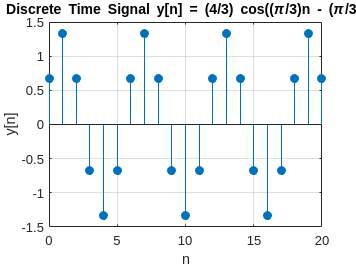

% Plotting the computed y[n]
n = 0:20; % Define the range 
y_n = (4/3) * cos((pi/3) * n - (pi/3));

% Plot the signal
stem(n, y_n, 'filled');
title('Discrete Time Signal y[n] = (4/3) cos((\pi/3)n - (\pi/3))');
xlabel('n');
ylabel('y[n]');
grid on;

*Verifying *$y_c[n]$* by first computing the convolution and plotting the result, then plotting the obtained mathematical expression from Part 1. The two graphs are the same.*

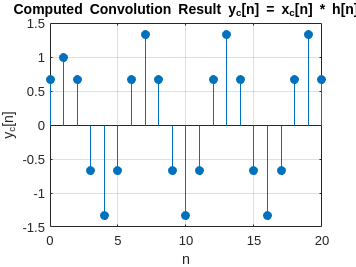

% Plotting the computed y_c[n] 
n = 0:20; % Define the range 
% Computing the convolution y_c[n] = x_c[n] * h[n] for verification
h = (1/3)*ones(1,3); % Define the impulse response h[n]
x_c = 2*cos(pi/3*n); % Define the input signal x_c[n]

% Zero-pad x_c to make sure the convolution result is the same length as n
x_c_padded = [x_c, zeros(1, length(h) - 1)];
y_c = conv(x_c_padded, h ); % y_c[n] = x_c[n] * h[n]

% Plot the signal
figure;
stem(n, y_c(1:length(n)), 'filled');
title('Computed Convolution Result y_{c}[n] = x_{c}[n] * h[n]');
xlabel('n');
ylabel('y_{c}[n]');
grid on; 

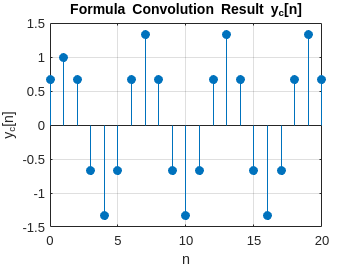


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plotting the formula y_c[n] obtained in Part 1
x_c = 2*cos(pi/3*n);

% Calculate y[n] for each value of n using the piecewise function
y = zeros(1, length(n));
for i = 1:length(n)
    if i >= 3
        y(i) = (1/3) * (x_c(i) + x_c(i-1) + x_c(i-2));
    elseif i == 2
        y(i) = (1/3) * (x_c(i) + x_c(i-1));
    elseif i == 1
        y(i) = (1/3) * x_c(i);
    end
end

% Plot the signal
stem(n, y, 'filled');
title('Formula Convolution Result y_{c}[n]');
xlabel('n');
ylabel('y_{c}[n]');
grid on;

*Plotting the transient response *$y_{tr}[n] = y_c[n] - y[n]$.  

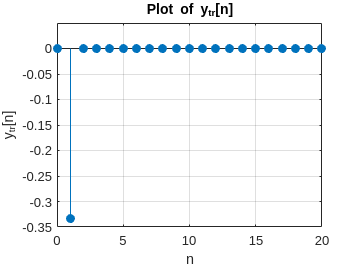

% Plotting thecomputed y_tr[n] 
n = 0:20;  % Assuming we want to plot from n=0 to n=20

% Calculate y_tr[n] for each value of n using the piecewise function
y_tr = zeros(1, length(n));
for i = 1:length(n)
    if n(i) >= 2
        % for n >= 2
        y_tr(i) = (2/3)*(cos(pi/3*n(i)) + cos(pi/3*(n(i)-1)) + cos(pi/3*(n(i)-2))) - (4/3)*cos(pi/3*n(i) - pi/3);
    elseif n(i) == 1
        % for n = 1
        y_tr(i) = (2/3)*(cos(pi/3*n(i)) + cos(pi/3*(n(i)-1))) - (4/3)*cos(pi/3*n(i) - pi/3);
    elseif n(i) == 0
        % for n = 0
        y_tr(i) = (2/3)*cos(pi/3*n(i)) - (4/3)*cos(pi/3*n(i) - pi/3);
    end
end

% Plot the signal
stem(n, y_tr, 'filled');
title('Plot of y_{tr}[n]');
xlabel('n');
ylabel('y_{tr}[n]');
grid on;

### **Part 4**

**This section will now derive a general expression for the transient response **$y_{tr}[n]$** of a causal LTI system, for which the impulse response is **$h[n]$** when the input is a ‘causal sinusoid’ xc, i.e. a sinusoid that starts at time n = 0. Starting from the expression of the output of the LTI as a convolution sum **$\sum_{k = -\infty}^{k = +\infty} x[k] h[n-k] $**, it is shown that the transient response can be expressed as: **


$$y_{tr}[n] = -\sum_{k = n+1}^{k = +\infty} h[k] cos(\omega(n-k)) \text{ for } n \ge 0$$


*Using the definition of convolution:*


$$y_{c}[n]=\sum_{k=-\infty}^{\infty}h[k]\cos(\omega(n-k))u[n-k]$$


*Applying the *$u[n]$*step function: *


$$y_{c}[n]=\sum_{k=0}^{\infty}h[k]\cos(\omega(n-k))$$


*Assuming that the filter *$h$* has a length of *$L$ *and using the formula for the convolution of infinite sequences with a finite filter:*


$$y_{c}[n]=\sum_{k=0}^{\min(n,L)}h[k]\cos(\omega(n-k))$$


*At steady state, *$n \ge L$* and the above expression can be simplified to express the steady state response using the following equation:*


$$y[n]=\sum_{k=0}^{L}h[k]\cos(\omega(n-k))$$


*Using the formula for the transient response *$y_{tr}[n] = y_c[n]-y[n]$*: *


$$y_{tr}[n]=\sum_{k=0}^{\min(n,L)}h[k]\cos(\omega(n-k))  - \sum_{k=0}^{L}h[k]\cos(\omega(n-k))$$


*Since both summations have the same *$h[k]cos(\omega(n-k))$*, the first few terms cancel (depending on what is the *$n$*) and the equation is left with the values at *$n+1$,* such the lower bound of the summation of the second term gets updated to *$k=n+1$*and the first term gets removed. Leaving the following equation: *


$$y_{tr}[n]=  - \sum_{k=n+1}^{L}h[k]\cos(\omega(n-k))$$


*Since the length of the filter is not known, it can be assumed that*$L = \infty$*:*


$$y_{tr}[n]=  - \sum_{k=n+1}^{\infty}h[k]\cos(\omega(n-k))$$


### **Part 5**


$$\begin{array}{rl}
y_{tr}[n]=&-\sum_{k=n+1}^{\infty}h[k]\cos(\omega(n-k)) \\
=&-\sum_{k=n+1}^{\infty}\sum_{l=0}^2\frac{1}{3}{\delta}[k-l]2\cos(\frac{\pi}{3}(n-k))\\
=&-\frac{2}{3}\sum_{k=n+1}^{\infty}\sum_{l=0}^2{\delta}[k-l]\cos(\frac{\pi}{3}(n-k)) \\
=&-\frac{2}{3}\sum_{k=n+1}^{2}\cos(\frac{\pi}{3}(n-k)) \\
\end{array}$$


**Sources used to complete this section:**

- https://www.reddit.com/r/DSP/comments/w1ajdp/found_this_super_easy_way_of_doing_convolution/

- [https://dsp.stackexchange.com/questions/23988/why-is-the-output-of-an-lti-system-expressed-as-the-convolution-of-the-input-wit](https://dsp.stackexchange.com/questions/23988/why-is-the-output-of-an-lti-system-expressed-as-the-convolution-of-the-input-wit)

- [https://eceweb1.rutgers.edAssuming that the filter h as a length of :u/~orfanidi/intro2sp/2e/orfanidis-isp2e-1up.pdf](https://eceweb1.rutgers.edu/~orfanidi/intro2sp/2e/orfanidis-isp2e-1up.pdf)

## Appendix 

### *Exercise 3 Part 3*

function y = a2_filter(x, M, g)
    % Args:
    %   x: Input signal 
    %   M: Delay length 
    %   g: Gain 
    %
    % Returns:
    %   y: Output signal (vector) after processing through the filter.
    %
    % The filter implements the following difference equations:
    %   v[n] = x[n] + g*v[n-M]
    %   y[n] = v[n-M] - g*v[n]

    % Filter 1
    % v[n] = x[n] + g*v[n-M]
    b_1 = 1; % feedforward coefficients
    a_1 = [1, zeros(1, M-1), -g]; % feedbackward coefficient
    
    % Filter 2
    % y[n] = v[n-M] - g*v[n]
    b_2 = [-g, zeros(1, M-1), 1]; % feedforward coefficients
    a_2 = 1; % feedbackward coefficient

    v = filter(b_1, a_1, x);
    y = filter(b_2, a_2, v);
end

### *Helper Functions*

function duration = get_impulse_duration(M, g)
    duration = round(M*(1 - ((log10(1000*(1-g.^2))) ./ (log10(abs(g))))));
end

function impulse = get_impulse(duration)
    impulse = [1; zeros(duration-1, 1)];
end

